# Optimization

## Matlab: fminbnd

`fminbnd` finds the minimum of a single variable function in an interval. It is wise to plot the function first so that the minimums position is found approximately.

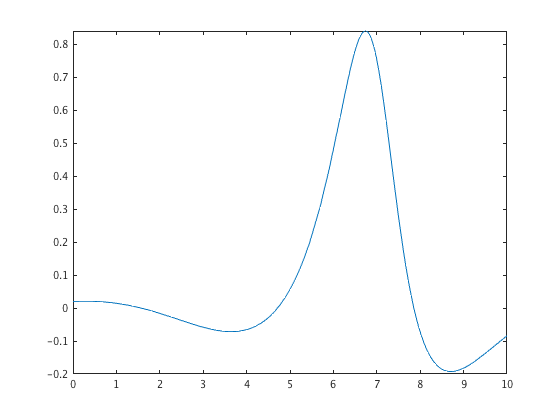

f = @(x) cos(x)./(1+(x-7).^2);
fplot(f, [0 10])

From the picture we see that the minimum lies somewhere between 8 and 9, so we set the interval to `[8, 9]` .

xmin = fminbnd(f, 8, 9)

xmin = 8.7076

fmin = f(xmin) %#ok<*NASGU,*ASGLU>

fmin = -0.1925

`fminbnd` also returns the minimum value as a second output argument. We also give a third output argument. Here `flag = 1`, which indicates that the iteration converged to a solution within the given tolerances.

[xmin, fmin, flag] = fminbnd(f, 8, 9)

xmin = 8.7076

fmin = -0.1925

flag = 1

We can give options to `fminbnd` with the `optimset` command. Here we give options to show all iterations.

options = optimset('Display', 'iter')

options = struct with fields:
                   Display: 'iter'
               MaxFunEvals: []
                   MaxIter: []
                    TolFun: []
                      TolX: []
               FunValCheck: []
                 OutputFcn: []
                  PlotFcns: []
           ActiveConstrTol: []
                 Algorithm: []
    AlwaysHonorConstraints: []
           DerivativeCheck: []
               Diagnostics: []
             DiffMaxChange: []
             DiffMinChange: []
            FinDiffRelStep: []
               FinDiffType: []
         GoalsExactAchieve: []
                GradConstr: []
                   GradObj: []
                   HessFcn: []
                   Hessian: []
                  HessMult: []
               HessPattern: []
                HessUpdate: []
          InitBarrierParam: []
     InitTrustRegionRadius: []
                  Jacobian: []
                 JacobMult: []
              JacobPattern: []
                LargeScale: []
     

fminbnd(f, 8, 9, options)

 
 Func-count     x          f(x)         Procedure
    1        8.38197    -0.173135        initial
    2        8.61803    -0.191223        golden
    3        8.76393    -0.192018        golden
    4        8.70559    -0.192462        parabolic
    5        8.70924    -0.192462        parabolic
    6        8.70757    -0.192463        parabolic
    7        8.70754    -0.192463        parabolic
    8        8.70761    -0.192463        parabolic
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 



ans = 8.7076

Calling `optimset` without arguments shows a complete list of valid options (not all functions make use of all options).

optimset

                Display: [ off | iter | iter-detailed | notify | notify-detailed | final | final-detailed ]
            MaxFunEvals: [ positive scalar ]
                MaxIter: [ positive scalar ]
                 TolFun: [ positive scalar ]
                   TolX: [ positive scalar ]
            FunValCheck: [ on | {off} ]
              OutputFcn: [ function | {[]} ]
               PlotFcns: [ function | {[]} ]
              Algorithm: [ active-set | interior-point | interior-point-convex | levenberg-marquardt | ...
                           sqp | trust-region-dogleg | trust-region-reflective ]
 AlwaysHonorConstraints: [ none | {bounds} ]
        DerivativeCheck: [ on | {off} ]
            Diagnostics: [ on | {off} ]
          DiffMaxChange: [ positive scalar | {Inf} ]
          DiffMinChange: [ positive scalar | {0} ]
         FinDiffRelStep: [ positive vector | positive scalar | {[]} ]
            FinDiffType: [ {forward} | central ]
      GoalsExactAchieve: [ positive scalar | {

`optimget` shows the value of a specified option.

optimget(options, 'Display')

ans = 'iter'

Embiggening the interval gives a local minimum as seen from the plot. Here the 4th output argument is a structure containing information about the optimization.

[xmin, ymin, flag, output] = fminbnd(f, 0, 10, options)

 
 Func-count     x          f(x)         Procedure
    1        3.81966    -0.070069        initial
    2        6.18034     0.594982        golden
    3        2.36068    -0.031535        golden
    4        3.25387   -0.0660994        parabolic
    5        3.69832   -0.0713371        parabolic
    6        3.62603     -0.07146        parabolic
    7        3.64336   -0.0714707        parabolic
    8        3.64204   -0.0714708        parabolic
    9        3.64221   -0.0714708        parabolic
   10        3.64224   -0.0714708        parabolic
   11        3.64217   -0.0714708        parabolic
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 



xmin = 3.6422

ymin = -0.0715

flag = 1

output = struct with fields:
    iterations: 10
     funcCount: 11
     algorithm: 'golden section search, parabolic interpolation'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵'


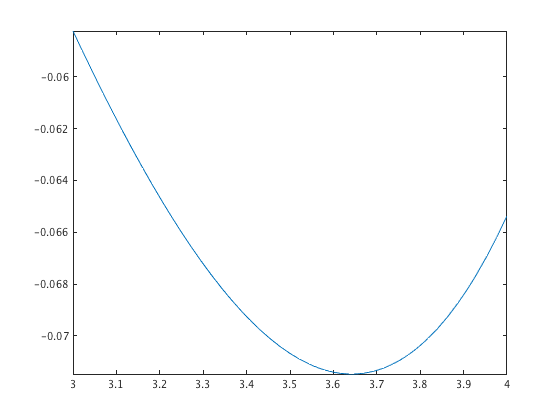

fplot(f, [3, 4])

We find the maximum by minimizing `-f`.

xmax = fminbnd(@(x)-f(x), 0, 10)

xmax = 6.7385

fmax = f(xmax)

fmax = 0.8406

This plots the function values.

ans = 8.7076

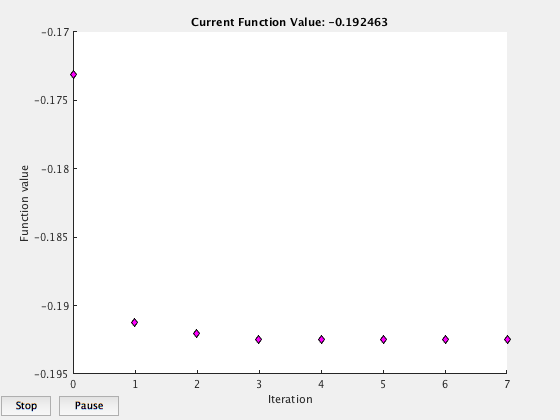

options = optimset('PlotFcns', @optimplotfval);
fminbnd(f, 8, 9, options)

This plots the function values and the current point.

ans = 8.7076

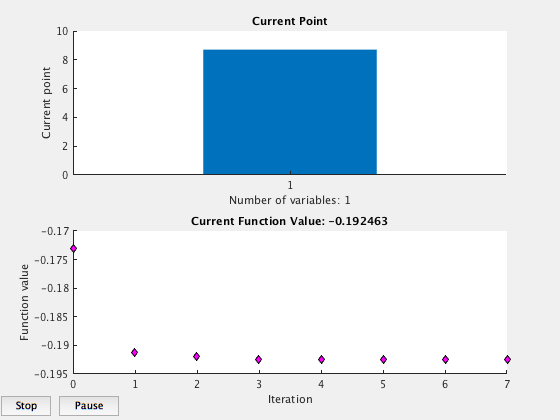

options = optimset('PlotFcns', {@optimplotx, @optimplotfval});
fminbnd(f, 8, 9, options)

## Matlab: fminsearch

`fminsearch` minimizes multivariable functions using the Nelder-Mead derivative free search method.

Let us find the minimum of the function

                
$$f(x_1, x_2, x_3) = x_1^2 + 2.5^{\sin(x_2)} - (x_1 x_2 x_3)^2$$


With the initial value $(0, 0, 0)$ the algorithm diverges.

ff = @(x) x(1)^2 + 2.5^sin(x(2)) - (x(1)*x(2)*x(3))^2;
[xmin, ymin, flag, output] = fminsearch(ff, [0; 0; 0])

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: -1196253764580254378250472491494852343831605170126930992279557829528897303700957588290984845801062164986601590524485592324982817247602216720276480446747906852637516314966510375832620073261954724544594221981106636767461280753167624644780345283648091066268986718696991093553618574631777590130208234243358720.000000 



xmin =    1.0e+50 *

    1.9090
   -8.3180
    2.1781


ymin = -1.1963e+303

flag = 0

output = struct with fields:
    iterations: 301
     funcCount: 601
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Exiting: Maximum number of function evaluations has been exceeded↵         - increase MaxFunEvals option.↵         Current function value: -1196253764580254378250472491494852343831605170126930992279557829528897303700957588290984845801062164986601590524485592324982817247602216720276480446747906852637516314966510375832620073261954724544594221981106636767461280753167624644780345283648091066268986718696991093553618574631777590130208234243358720.000000 ↵'


Let us try another initial value $(0, -1, 0)$. Now the algorithm converges.

[xmin, ymin, flag, output] = fminsearch(ff, [0; -1; 0])

xmin =    -0.0011
   -1.5707
   -0.0018


ymin = 0.4000

flag = 1

output = struct with fields:
    iterations: 41
     funcCount: 82
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


Plot the function values and show iterations.

 
 Iteration   Func-count     min f(x)         Procedure
     0            1         0.462535         
     1            4         0.451666         initial simplex
     2            5         0.451666         reflect
     3            7         0.445052         expand
     4            9         0.430642         expand
     5           11         0.421216         expand
     6           13         0.406474         expand
     7           15         0.400387         expand
     8           16         0.400387         reflect
     9           18         0.400387         contract outside
    10           20         0.400387         contract inside
    11           22         0.400157         contract outside
    12           24         0.400157         contract inside
    13           26         0.400044         contract inside
    14           28         0.400044         contract inside
    15           30         0.400041         contract inside
    16           32         0.400024     

xmin =    -0.0011
   -1.5707
   -0.0018


ymin = 0.4000

flag = 1

output = struct with fields:
    iterations: 41
     funcCount: 82
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


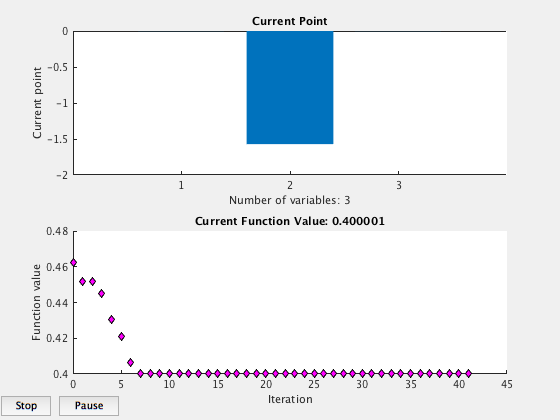

options = optimset('Display', 'iter', 'PlotFcns', {@optimplotx, @optimplotfval});
[xmin, ymin, flag, output] = fminsearch(ff, [0; -1; 0], options)

`fminsearch` works also for univariate functions.

options = optimset('Display', 'iter');
[xmin, ymin, flag, output] = fminsearch(f, 8, options)

 
 Iteration   Func-count     min f(x)         Procedure
     0            1         -0.07275         
     1            2        -0.175435         initial simplex
     2            4        -0.191296         reflect
     3            6        -0.191296         contract inside
     4            8        -0.192454         contract inside
     5           10        -0.192454         contract inside
     6           12        -0.192454         contract inside
     7           14        -0.192459         contract inside
     8           16        -0.192462         contract inside
     9           18        -0.192462         contract inside
    10           20        -0.192463         contract inside
    11           22        -0.192463         contract inside
    12           24        -0.192463         contract inside
    13           26        -0.192463         contract inside
    14           28        -0.192463         contract inside
 
Optimization terminated:
 the current x satisfies

xmin = 8.7075

ymin = -0.1925

flag = 1

output = struct with fields:
    iterations: 14
     funcCount: 28
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


## Optimization Toolbox: fminunc

Optimization Toolbox has large collection of functions. `fminunc` solves an unconstrained minimization problem for multivariable functions. Here we get the same solution as before.

options = optimset('Display', 'iter');
[xmin, ymin, flag, output] = fminunc(ff, [0; -1; 0], options)

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           4         0.462535                         0.229
     1           8         0.421775              1           0.13  
     2          12         0.400347              1          0.016  
     3          16              0.4              1       0.000589  
     4          20              0.4              1       8.09e-06  
     5          28              0.4       0.217316       2.42e-07  

Local minimum found.

Optimization completed because the size of the gradient is less than
the default value of the 

xmin =    -0.0000
   -1.5708
         0


ymin = 0.4000

flag = 1

output = struct with fields:
       iterations: 5
        funcCount: 28
         stepsize: 4.0569e-06
     lssteplength: 0.2173
    firstorderopt: 2.4190e-07
        algorithm: 'quasi-newton'
          message: 'Local minimum found.↵↵Optimization completed because the size of the gradient is less than↵the default value of the optimality tolerance.↵↵Stopping criteria details:↵↵Optimization completed: The first-order optimality measure, 1.968306e-07, is less ↵than options.OptimalityTolerance = 1.000000e-06.↵↵Optimization Metric                                          Options↵relative norm(gradient) =   1.97e-07             OptimalityTolerance =   1e-06 (default)'


Giving the solver the gradient can improve the solution. We write the new function below, which returns the gradient as the second output argument. It can't be an anonymous function because of the `if`, so we must write it as an m-file function, see the end of the file.

`function [f, g] = ffg(x)`

`f = x(1)^2 + 2.5^sin(x(2)) - (x(1)*x(2)*x(3))^2;`

`if nargout > 1`

`    g = [2*x(1) - 2*x(1)*(x(2)*x(3))^2;`

`        log(2.5)*cos(x(2))*2.5^sin(x(2)) - 2*x(2)*(x(1)*x(3))^2;`

`         - 2*x(3)*(x(1)*x(2))^2];`

`end`

Now we must set the option `GradObj` to `on`. Now the number of iterations is smaller, and the number of function evaluations is significantly smaller.

options = optimset('Display', 'iter', 'GradObj', 'on');
[xmin, ymin, flag, output] = fminunc(@ffg, [0; -1; 0], options)


                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0           0.462535                         0.229                
     1           0.401282       0.487215         0.0307           1
     2                0.4       0.083243       0.000124           1
     3                0.4    0.000338292       8.64e-12           1

Local minimum found.

Optimization completed because the size of the gradient is less than
the default value of the optimality tolerance.

<

xmin =          0
   -1.5708
         0


ymin = 0.4000

flag = 1

output = struct with fields:
         iterations: 3
          funcCount: 4
           stepsize: 3.3829e-04
       cgiterations: 3
      firstorderopt: 8.6378e-12
          algorithm: 'trust-region'
            message: 'Local minimum found.↵↵Optimization completed because the size of the gradient is less than↵the default value of the optimality tolerance.↵↵Stopping criteria details:↵↵Optimization completed: The first-order optimality measure, 8.637848e-12, ↵is less than options.OptimalityTolerance = 1.000000e-06, and no negative/zero↵curvature is detected in the trust-region model.↵↵Optimization Metric                                        Options↵relative first-order optimality =   8.64e-12   OptimalityTolerance =   1e-06 (default)'
    constrviolation: []


## Optimization Toolbox: fmincon

`fmincon` solves a constrained minimization problem for multivariable functions. We find the maximum of the function $f(x) = x_1 x_2 x_3$ subject to the constraint $0 \le x_1 + 2x_2 + 2x_3 \le 72$. We change maximization to minimization in the usual way and write the constraint as the two linear constraints: $-x_1 - 2x_2 - 2x_3 \le 0$ and $x_1 + 2x_2 + 2x_3 \le 72$. Notice that we pass empty matrices for unused arguments.

fff = @(x) -x(1)*x(2)*x(3);
A = [-1 -2 -2; 1 2 2]; b = [0; 72]; % The linear inequality constraints
x0 = [10; 10; 10];
options = optimset('Display', 'iter');
[xmin, fmin, flag, output] = fmincon(fff, x0, A, b, [], [], [], [], [], options)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       4   -1.000000e+03    0.000e+00    9.899e+01
    1       8   -3.055040e+03    0.000e+00    2.098e+02    7.873e+00
    2      12   -3.219148e+03    0.000e+00    6.463e+01    1.950e+00
    3      16   -3.451737e+03    0.000e+00    1.465e+01    6.335e+00
    4      20   -3.455915e+03    0.000e+00    1.420e+00    8.879e-01
    5      24   -3.456000e+03    0.000e+00    2.787e-02    1.232e-01
    6      28   -3.456000e+03    0.000e+00    1.947e-02    2.715e-03
    7      35   -3.456000e+03    0.000e+00    1.117e-02    2.066e-03
    8      39   -3.456000e+03    0.000e+00    5.565e-04    1.679e-03
    9      43   -3.456000e+03    0.000e+00    1.028e-05    4.731e-05

Local minimum found that satisfies the constraints.

Optimizati

xmin =    24.0000
   12.0000
   12.0000


fmin = -3.4560e+03

flag = 1

output = struct with fields:
         iterations: 9
          funcCount: 43
    constrviolation: 0
           stepsize: 4.7311e-05
          algorithm: 'interior-point'
      firstorderopt: 1.0278e-05
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the default value of the optimality tolerance,↵and constraints are satisfied to within the default value of the constraint tolerance.↵↵Stopping criteria details:↵↵Optimization completed: The relative first-order optimality measure, 3.568697e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.↵↵Optimization Metric                                            Options↵relative first-order optimality =   3.57e-08       OptimalityTolerance =   1e-06 (default)↵relative m

fmax = -fmin

fmax = 3.4560e+03

We can again improve the algorithm by giving the gradient. We use the `deal` function to return more than one argument from the anonymous function.

fffg = @(x) deal(-x(1)*x(2)*x(3), [-x(2)*x(3); -x(1)*x(3); -x(1)*x(2)]);
options = optimset('Display', 'iter', 'GradObj', 'on');
[xmin, fmin, flag, output] = fmincon(fffg, x0, A, b, [], [], [], [], [], options)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1   -1.000000e+03    0.000e+00    9.899e+01
    1       2   -3.055040e+03    0.000e+00    2.098e+02    7.873e+00
    2       3   -3.219148e+03    0.000e+00    6.463e+01    1.950e+00
    3       4   -3.451737e+03    0.000e+00    1.465e+01    6.335e+00
    4       5   -3.455915e+03    0.000e+00    1.420e+00    8.879e-01
    5       6   -3.456000e+03    0.000e+00    2.704e-02    1.232e-01
    6       7   -3.456000e+03    0.000e+00    7.819e-05    2.438e-03

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
<a href = "matlab: helpview([docroot '/toolbox/optim/msg_csh/optim_msg_csh.map'],'feasible_directions','CSHelpWindow');">feasible directions<

xmin =    24.0000
   12.0000
   12.0000


fmin = -3.4560e+03

flag = 1

output = struct with fields:
         iterations: 6
          funcCount: 7
    constrviolation: 0
           stepsize: 0.0024
          algorithm: 'interior-point'
      firstorderopt: 7.8194e-05
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the default value of the optimality tolerance,↵and constraints are satisfied to within the default value of the constraint tolerance.↵↵Stopping criteria details:↵↵Optimization completed: The relative first-order optimality measure, 2.715082e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.↵↵Optimization Metric                                            Options↵relative first-order optimality =   2.72e-07       OptimalityTolerance =   1e-06 (default)↵relative max(co

fmax = -fmin

fmax = 3.4560e+03

The variables can also have bounds. Let us find the minimum of $f(x) = 2x_1^2 - 1.05x_1^4 + x_1^6/6 + x_1 x_2 + x_2^2$ in the square $x_1, x_2 \in [-2, 2]$. First we define `f4` as a function of two arguments, which is convenient for plotting the surface and contours. Since the objective function has to be a function of one vector argument, we pass `fmincon` an anonymous function that calls `f4`. Here we don't have linear constraints, so they are set to empty matrices.

f4 = @(x1, x2) 2*x1.^2 - 1.05*x1.^4 + x1.^6/6 + x1.*x2 + x2.^2;
options = optimset('Display', 'iter');
lb = [-2;-2]; ub = [2;2]; % Lower and upper bounds
[xmin, fmin, flag, output] = fmincon(@(x)f4(x(1), x(2)), [1;1], [], [], [], [],...
    lb, ub, [], options)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    3.116667e+00    0.000e+00    2.842e+00
    1       7    1.083651e-01    0.000e+00    5.948e-01    1.549e+00
    2      11    4.400271e-02    0.000e+00    4.738e-01    2.520e-01
    3      14    1.132933e-03    0.000e+00    7.560e-02    2.228e-01
    4      17    3.052750e-07    0.000e+00    1.047e-02    3.087e-02
    5      20    3.734763e-11    0.000e+00    1.030e-04    5.902e-04
    6      23    4.408995e-14    0.000e+00    1.000e-06    4.656e-06
    7      26    2.174211e-16    0.000e+00    5.723e-08    1.755e-07

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


xmin =    1.0e-07 *

    0.0983
   -0.1187


fmin = 2.1742e-16

flag = 1

output = struct with fields:
         iterations: 7
          funcCount: 26
    constrviolation: 0
           stepsize: 1.7551e-07
          algorithm: 'interior-point'
      firstorderopt: 5.7230e-08
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the default value of the optimality tolerance,↵and constraints are satisfied to within the default value of the constraint tolerance.↵↵Stopping criteria details:↵↵Optimization completed: The relative first-order optimality measure, 5.723003e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.↵↵Optimization Metric                                            Options↵relative first-order optimality =   5.72e-08       OptimalityTolerance =   1e-06 (default)↵relative m

Now plot the surface with the minimum point.

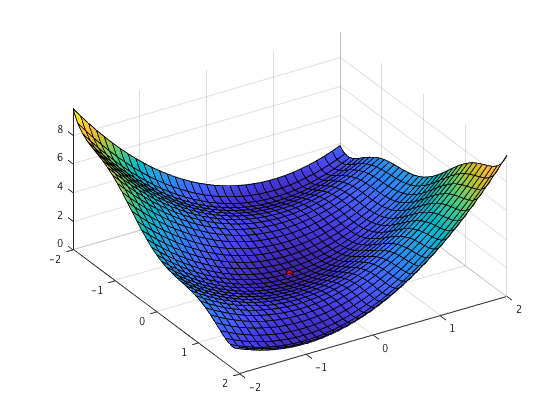

clf
fsurf(f4, [-2 2])
view(58, 46)
hold on
plot3(xmin(1), xmin(2), fmin, 'o', 'MarkerFaceColor', 'r',...
	'MarkerSize', 7, 'MarkerEdgeColor', 'black')
hold off

Next we plot the contours with the minimizer. We can't use `fcontour` because it doesn't allow setting the contour levels.

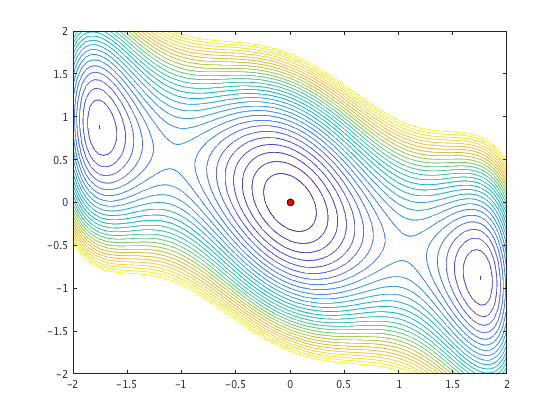

[X1, X2] = meshgrid(linspace(-2, 2, 100));
F = f4(X1, X2);
contour(X1, X2, F, 0:0.1:3)
hold on
plot(xmin(1), xmin(2), 'o', 'MarkerFaceColor', 'r',...
	'MarkerSize', 7, 'MarkerEdgeColor', 'black')
hold off

Nonlinear constraints are also allowed. Let us find the minimum of the function $f(x) = (x_1 - 1)^2 + (x_2 - 2)^2$ subject to the constraint $4x_2 - x_1^2 \le 0$. A handle to the constraint function is given as the second to last argument, and it must return both the nonlinear equality and inequality constraints. Here we don't have equality constraints, so we return an empty matrix as the second output argument. Notice that we start from an infeasible point.

f5 = @(x) (x(1) - 1)^2 + (x(2) - 2)^2;
f5con = @(x) deal(4*x(2) - x(1)^2, []);
options = optimset('Display', 'iter');
[xmin, fmin, flag, output] = fmincon(f5, [1;1], [], [], [], [],...
    [], [], f5con, options)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3    1.000000e+00    3.000e+00    7.996e-01
    1       6    2.799057e+00    0.000e+00    5.605e-01    1.147e+00
    2       9    2.165365e+00    0.000e+00    3.069e-01    3.528e-01
    3      12    2.109207e+00    0.000e+00    1.107e-01    1.900e-01
    4      15    2.021803e+00    0.000e+00    2.188e-02    3.063e-02
    5      18    2.000335e+00    0.000e+00    3.353e-04    7.956e-03
    6      21    2.000002e+00    0.000e+00    2.027e-06    1.178e-04
    7      24    2.000000e+00    0.000e+00    2.000e-08    1.108e-06

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


xmin =     2.0000
    1.0000


fmin = 2.0000

flag = 1

output = struct with fields:
         iterations: 7
          funcCount: 24
    constrviolation: 0
           stepsize: 1.1082e-06
          algorithm: 'interior-point'
      firstorderopt: 2.0001e-08
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the default value of the optimality tolerance,↵and constraints are satisfied to within the default value of the constraint tolerance.↵↵Stopping criteria details:↵↵Optimization completed: The relative first-order optimality measure, 1.000066e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.↵↵Optimization Metric                                            Options↵relative first-order optimality =   1.00e-08       OptimalityTolerance =   1e-06 (default)↵relative m

We can again improve things by giving the gradients of the objective and constraint functions. For this we must set the options `GradObj` and `GradConstr` to `on`. We modify `f5` to return two arguments and `f5con` to return four arguments. The 3rd and 4th arguments are matrices whose columns are the gradients of the inequality and equality constraints, respectively.

f5g = @(x) deal((x(1) - 1)^2 + (x(2) - 2)^2, [2*(x(1) - 1); 2*(x(2) - 2)]);
f5cong = @(x) deal(4*x(2) - x(1)^2, [], [-2*x(1); 4], []);
options = optimset('Display', 'iter', 'GradObj', 'on', 'GradConstr', 'on');
[xmin, fmin, flag, output] = fmincon(f5g, [1;1], [], [], [], [],...
    [], [], f5cong, options)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    1.000000e+00    3.000e+00    7.996e-01
    1       2    2.799057e+00    0.000e+00    5.605e-01    1.147e+00
    2       3    2.165365e+00    0.000e+00    3.069e-01    3.528e-01
    3       4    2.109207e+00    0.000e+00    1.107e-01    1.900e-01
    4       5    2.021803e+00    0.000e+00    2.188e-02    3.063e-02
    5       6    2.000335e+00    0.000e+00    3.353e-04    7.956e-03
    6       7    2.000002e+00    0.000e+00    2.027e-06    1.178e-04
    7       8    2.000000e+00    0.000e+00    2.000e-08    1.101e-06

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 


xmin =     2.0000
    1.0000


fmin = 2.0000

flag = 1

output = struct with fields:
         iterations: 7
          funcCount: 8
    constrviolation: 0
           stepsize: 1.1007e-06
          algorithm: 'interior-point'
      firstorderopt: 2.0001e-08
       cgiterations: 0
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the default value of the optimality tolerance,↵and constraints are satisfied to within the default value of the constraint tolerance.↵↵Stopping criteria details:↵↵Optimization completed: The relative first-order optimality measure, 1.000063e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.↵↵Optimization Metric                                            Options↵relative first-order optimality =   1.00e-08       OptimalityTolerance =   1e-06 (default)↵relative ma

Let us find the minimum of


$$f(x) = 100(x_2 - x_1^2)^2 + (x_1 - 1)^2 + 100(x_3 - x_2^2)^2 + (x_2 - 1)^2$$


subject to the constraints


$$g_1(x) = x_3^2 - 2x_1 x_2 \le 0$$



$$g_2(x) = x_1^3 - 3x_2^2 x_3 \le 0$$



$$h(x) = x_1^2 + 2x_2^2 + x_3^2 = 4$$


We write `f` so that it returns also the gradient.

`function [f, df] = f6g(x)`

`f = 100*(x(2) - x(1)^2)^2 + 100*(x(3) - x(2)^2)^2 + (x(1) - 1)^2 + (x(2) - 1)^2;`

`if nargout > 1`

`    df = [-400*x(1)*(x(2) - x(1)^2) + 2*(x(1) - 1);`

`        200*(x(2) - x(1)^2) - 400*x(2)*(x(3) - x(2)^2) + 2*(x(2) - 1);`

`        200*(x(3) - x(2)^2)];`

`end`

The constraints are also written to return the gradients. Notice that the third return argument is a matrix with the first and second columns the gradients of $g_1$ and $g_2$, respectively. It is actually the transpose of the Jacobian of $g$.

`function [g, h, dg, dh] = f6cong(x)`

`g = [x(3)^2 - 2*x(1)*x(2); x(1)^3 - 3*x(2)^2*x(3)];`

`h = x(1)^2 + 2*x(2)^2 + x(3)^2 - 4;`

`if nargout > 2`

`    dg = [-2*x(2), 3*x(1)^2; -2*x(1), -6*x(2)*x(3); 2*x(3), -3*x(2)^2];`

`    dh = [2*x(1); 4*x(2); 2*x(3)];`

`end`

options = optimset('Display', 'iter', 'GradObj', 'on', 'GradConstr', 'on');
[xmin, fmin, flag, output] = fmincon(@f6g, [0;0;0], [], [], [], [],...
    [], [], @f6cong, options)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    2.000000e+00    4.000e+00    2.000e+00
    1      11    1.959567e+00    3.998e+00    2.492e+00    3.248e-02
    2      13    1.901743e+00    3.993e+00    4.429e+00    4.688e-02
    3      18    1.668856e+00    3.964e+00    7.650e-01    1.054e-01
    4      20    1.359465e+00    3.764e+00    1.267e+01    2.779e-01
    5      22    1.368463e+00    3.693e+00    2.249e+01    8.402e-02
    6      23    9.658034e-01    3.577e+00    2.032e+01    9.304e-02
    7      26    1.858511e+01    1.378e+00    1.060e+02    9.373e-01
    8      28    1.213338e+01    6.230e-01    9.301e+01    2.349e-01
    9      31    9.201974e-01    4.349e-01    6.292e+01    1.719e-01
   10      32    1.762252e+00    1.533e-02    3.135e+01    1.135e-01
   11      36    1.388666e+00    1.744e-02    5.873e+01    5.572e-02
   12      37    4.656220e-01    5.526e-04    2

xmin =     1.0000
    1.0000
    1.0000


fmin = 2.1369e-18

flag = 1

output = struct with fields:
         iterations: 21
          funcCount: 46
    constrviolation: 0
           stepsize: 8.2215e-09
          algorithm: 'interior-point'
      firstorderopt: 2.0000e-08
       cgiterations: 7
            message: 'Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the default value of the optimality tolerance,↵and constraints are satisfied to within the default value of the constraint tolerance.↵↵Stopping criteria details:↵↵Optimization completed: The relative first-order optimality measure, 2.000005e-08,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.↵↵Optimization Metric                                            Options↵relative first-order optimality =   2.00e-08       OptimalityTolerance =   1e-06 (default)↵relative 

function [f, g] = ffg(x)
    f = x(1)^2 + 2.5^sin(x(2)) - (x(1)*x(2)*x(3))^2;
    if nargout > 1
        g = [2*x(1) - 2*x(1)*(x(2)*x(3))^2;
            log(2.5)*cos(x(2))*2.5^sin(x(2)) - 2*x(2)*(x(1)*x(3))^2;
            - 2*x(3)*(x(1)*x(2))^2];
    end
end

function [f, df] = f6g(x)
    f = 100*(x(2) - x(1)^2)^2 + 100*(x(3) - x(2)^2)^2 + (x(1) - 1)^2 + (x(2) - 1)^2;
    if nargout > 1
        df = [-400*x(1)*(x(2) - x(1)^2) + 2*(x(1) - 1);
            200*(x(2) - x(1)^2) - 400*x(2)*(x(3) - x(2)^2) + 2*(x(2) - 1);
            200*(x(3) - x(2)^2)];
    end
end

function [g, h, dg, dh] = f6cong(x)
    g = [x(3)^2 - 2*x(1)*x(2); x(1)^3 - 3*x(2)^2*x(3)];
    h = x(1)^2 + 2*x(2)^2 + x(3)^2 - 4;
    if nargout > 2
        dg = [-2*x(2), 3*x(1)^2; -2*x(1), -6*x(2)*x(3); 2*x(3), -3*x(2)^2];
        dh = [2*x(1); 4*x(2); 2*x(3)];
    end
end